clear all
close all
clc

load("ETDataMat.mat")


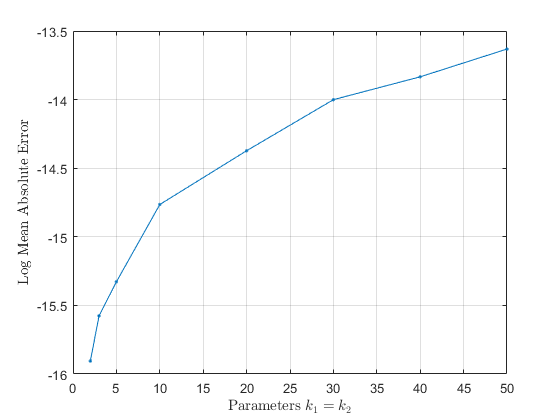



k = ETData(:,1);
mean = ETData(:,2);
std = ETData(:,3);
et = ETData(:,4);

figure
plot(k,mean,'.-')
grid on
xlabel('Parameters $k_1=k_2$',"Interpreter","latex")
ylabel('Log Mean Absolute Error',"Interpreter","latex")

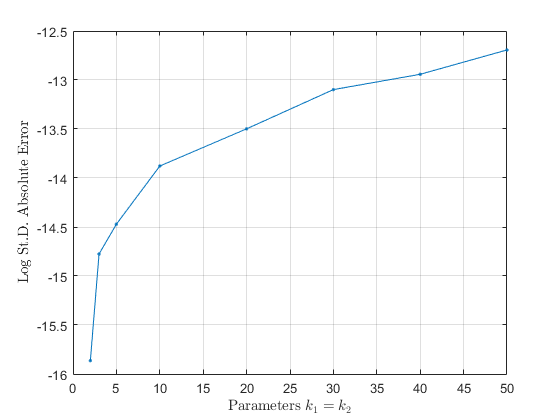


figure
plot(k,std,'.-')
grid on
xlabel('Parameters $k_1=k_2$',"Interpreter","latex")
ylabel('Log St.D. Absolute Error',"Interpreter","latex")

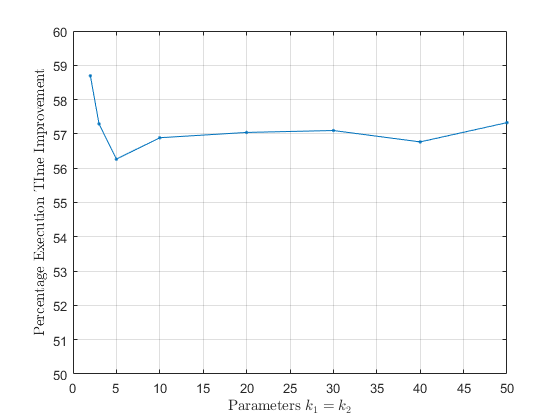


figure
plot(k,et,'.-')
grid on
xlabel('Parameters $k_1=k_2$',"Interpreter","latex")
ylabel('Percentage Execution TIme Improvement',"Interpreter","latex")
axis([0,50,50,60])

k = ETData2(1,:)

k =      1     3     5     7     9    11    15    20


mean_SRM1 = ETData2(2,:)

mean_SRM1 =   -15.2443  -15.4948  -15.5680  -15.6204  -15.6462  -15.6455  -15.6810  -15.6825


mean_SRM2 = ETData2(3,:)

mean_SRM2 =   -14.2928  -13.9244  -13.8577  -13.8735  -13.8928  -14.0312  -14.0312  -13.9612


mean_SRM3 = ETData2(4,:)

mean_SRM3 =   -14.1688  -14.1907  -14.2599  -14.1944  -14.1707  -14.2014  -14.2372  -14.2264


mean_SRM4 = ETData2(5,:)

mean_SRM4 =   -14.0322  -13.8418  -13.7685  -13.7562  -13.7406  -13.7441  -13.8124  -13.7815


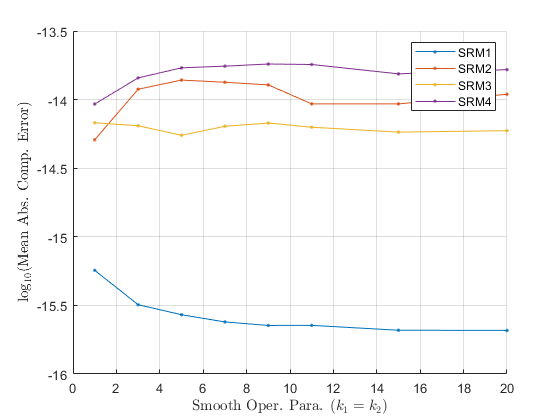


figure
hold on
plot(k,mean_SRM1,'.-',"DisplayName","SRM1")
plot(k,mean_SRM2,'.-',"DisplayName","SRM2")
plot(k,mean_SRM3,'.-',"DisplayName","SRM3")
plot(k,mean_SRM4,'.-',"DisplayName","SRM4")
xlabel('Smooth Oper. Para. ($k_1=k_2$)',"Interpreter","latex")
ylabel('$\log_{10}($Mean Abs. Comp. Error$)$',"Interpreter","latex")
legend
grid on 